# DMD pattern Design

## Special pattern generate

%% common params setting
dmd_size = 256; % dmd size
Cr = 10         % compressive ratio

Cr = 10

dmd_type = 'center_circle'

dmd_type = 'center_circle'

dmd_type:

'center_circle'

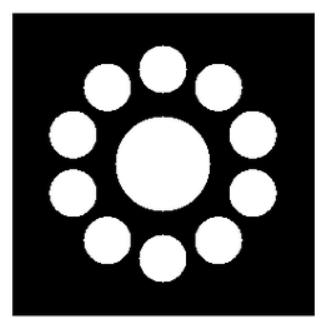

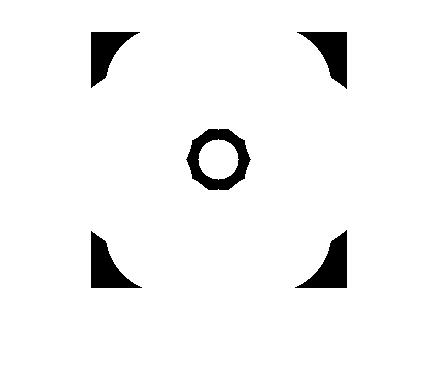

%% dmd generate
if strcmp(dmd_type, 'center_circle')
    % params
    center_circle_p = round([dmd_size; dmd_size]./2);
    center_circle_r = 20;
    out_cricle_r = 60;
    out_cricle_dist = 90; % distance between out circle and center circle
    
    % pre calc: out_cricle_position
    theta = 2*pi/Cr;
    roate_mtx = [cos(theta), sin(theta); -sin(theta), cos(theta)];
    out_circle_p = zeros(2, Cr);
    out_circle_p(:,1) = [dmd_size/2 - out_cricle_dist; dmd_size/2]; % first out circle
   
    for i = 2:Cr
        % pre out_circle's center coord (relative to dmd center)
        pre_circle_p = out_circle_p(:,i-1);
        pre_circle_p2center =  pre_circle_p - center_circle_p;
        cur_circle_p2center = roate_mtx*pre_circle_p2center;
        cur_circle_p = cur_circle_p2center + center_circle_p;
        out_circle_p(:,i) = cur_circle_p;
    end
    
    % generate dmd
    dmd = zeros([dmd_size dmd_size Cr]);
    for i = 1:Cr
        tmp_dmd = cyl(dmd_size, center_circle_r);
        tmp_dmd = cyl(tmp_dmd, out_cricle_r,  out_circle_p(:,i));
        dmd(:,:,i) = tmp_dmd;
    end
         
    % show
    dmd_sum = sum(dmd,3);
    dmd_sum(dmd_sum>0)=1;
    imshow(dmd_sum);
    
end

## save dmd

% saving_path = './designed_dmd/'
saving_path = 'E:\project\CACTI\simulation\config\dmd\designed_dmd\'

saving_path = 'E:\project\CACTI\simulation\config\dmd\designed_dmd\'

disp(datetime);

   2020-06-28 21:25:20


saving_name = [dmd_type '_dmd_' num2str(dmd_size) '_' num2str(Cr) 'f.mat'];
save([saving_path saving_name], 'dmd');

## append functions

function z = cyl(N,R,P)
% CYL generates samples of a continuous, aperiodic, unity-height cylinder 
% at the points specified in P with radius R (percent of the length) on a background 
% rectangle with size N.
% 
%   Input:
%   --------
%   - N: 2-elements int vector, background rectangle size
%	- P: 2-elements int vector,centre point of the cylinder, default=[0,0]
%	- R: float scalar, radius of the cylinder
%   Output:
%   --------
%   - z: unity-height cylinder 

% input check
if numel(N)==1
	N = [N,N];		% background size
	z = zeros(N);	% background
elseif ~isvector(N)
	z = N;			% background
	N = size(z);	% background size
end

if nargin < 3
	P = round(N./2);
end

x0 = P(1);
y0 = P(2);
L1 = N(1);
L2 = N(2);

[x,y]=meshgrid(linspace(1, L1, L1), linspace(1, L2, L2)); 
x = x';
y = y';

r = sqrt((x-x0).*(x-x0)+(y-y0).*(y-y0)); % distance map

z(r<=R) = 1;
end